# Using Hypothesis Testing for Model Assessment

## Pearson's Goodness of Fit Test

### Binomial Example

A game designer believes that a game he is developing will be won approximately 17% of the time. In order to test this belief, he concludes that a binomial distribution with 

n = 30;

 and 

p = 0.17;

should predict the probability that anyone who plays the game $n$ successive times will win during any $x$ of the 30 plays. The designer releases the game to 

NParticipants=50; 

people and asks each of them to play 30 times and record the number of times they won. The game designer records the frequency of each count of wins that appears in their data set.

wins=(0:30)';
empiricalFrequency=[2 0 3 6 14 10 8 4 1 1 0 1 zeros(1,19)]';

Then, the game designer computes the theoretical frequencies of observing each value of x by scaling the binomial distribution by the number of observations, or

theoreticalFrequency=binopdf(wins,n,p)*NParticipants;

Finally, the game designer, summarizes the possible numbers of wins, the empirical frequencies for each value, and the theoretical frequencies for each value in the following table:

data=table(wins,empiricalFrequency,theoreticalFrequency)

data = 31×3 table
       wins       empiricalFrequency    theoreticalFrequency
    __________    __________________    ____________________

    0.0000e+00        2.0000e+00             1.8677e-01     
    1.0000e+00        0.0000e+00             1.1476e+00     
    2.0000e+00        3.0000e+00             3.4083e+00     
    3.0000e+00        6.0000e+00             6.5156e+00     
    4.0000e+00        1.4000e+01             9.0079e+00     
    5.0000e+00        1.0000e+01             9.5940e+00     
    6.0000e+00        8.0000e+00             8.1877e+00     
    7.0000e+00        4.0000e+00             5.7497e+00     
    8.0000e+00        1.0000e+00             3.3857e+00     
    9.0000e+00        1.0000e+00             1.6951e+00     
    1.0000e+01        0.0000e+00             7.2911e-01     
    1.1000e+01        1.0000e+00             2.7152e-01     
    1.2000e+01        0.0

The designer visually compares the agreement between the empirical and theoretical probabilities by constructing a side by side bar graph:

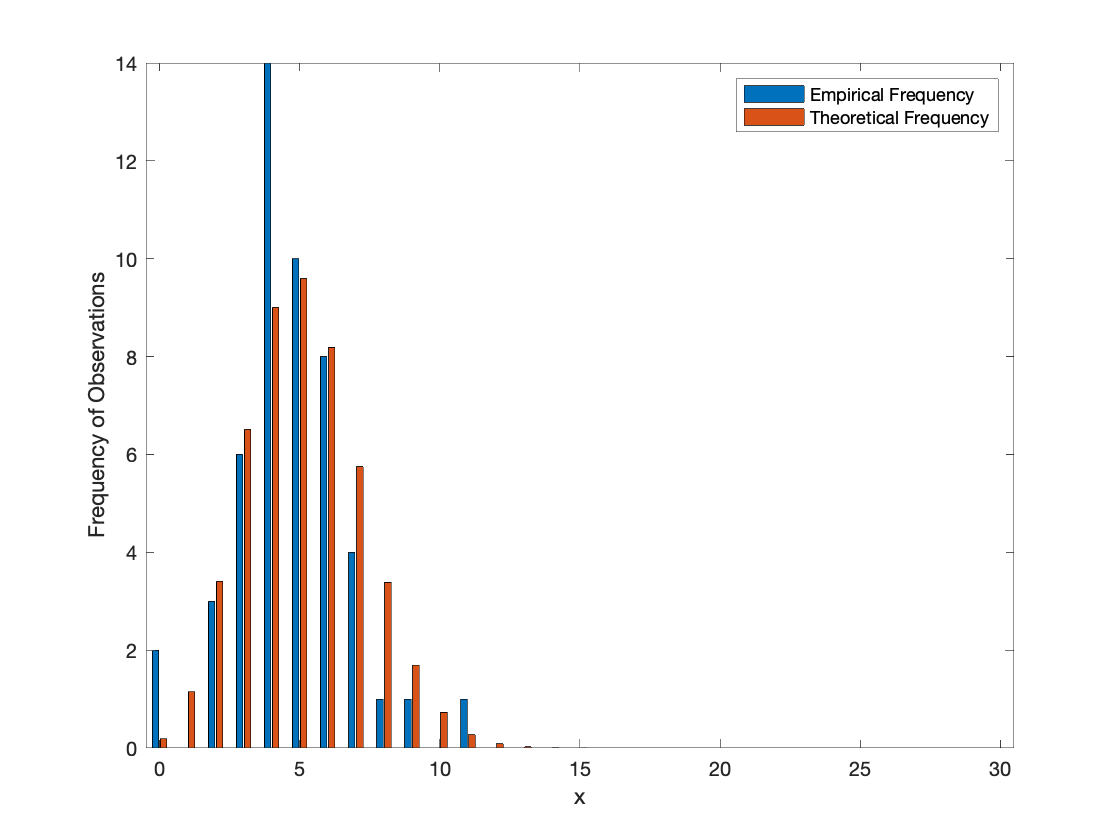

figure(1)
bar(wins,[empiricalFrequency, theoreticalFrequency])
xlabel('x')
ylabel('Frequency of Observations')
legend('Empirical Frequency','Theoretical Frequency')

The agreement looks good in a qualitative sense, but in order to quantify the level of agreement, the designer performs a $\chi^2$ goodness of fit test.

 To do so, he pools both his observed and experimental data into enough bins that are chosen to ensure that there are at least 5 observations per bin:

O=[5 6 14 10 8 7];
edges=[-1,2,3,4,5,6,30];
E=NParticipants*(binocdf(edges(2:end),n,p)-binocdf(edges(1:end-1),n,p));

Then, he computes the following test statistic for comparing these bin frequencies:

chi2stat=sum(((E-O).^2)./E)

chi2stat =    4.8945e+00


The designer needs to compare this statistic to an appropriate $\chi^2$ distribution. While there are 6 possible bins of frequencies being compared, there aren’t actually 6 degrees of freedom. The fact that we know that there were a total of 50 observations made means that once we know the frequencies of any five bins, the frequency of the sixth bin may be computed precisely. This causes us to lose one degree of freedom. Therefore, the designer compares his test statistic to the $\chi^2$ distribution with 

nu=5;

degrees of freedom. The density function for this distribution is depicted below

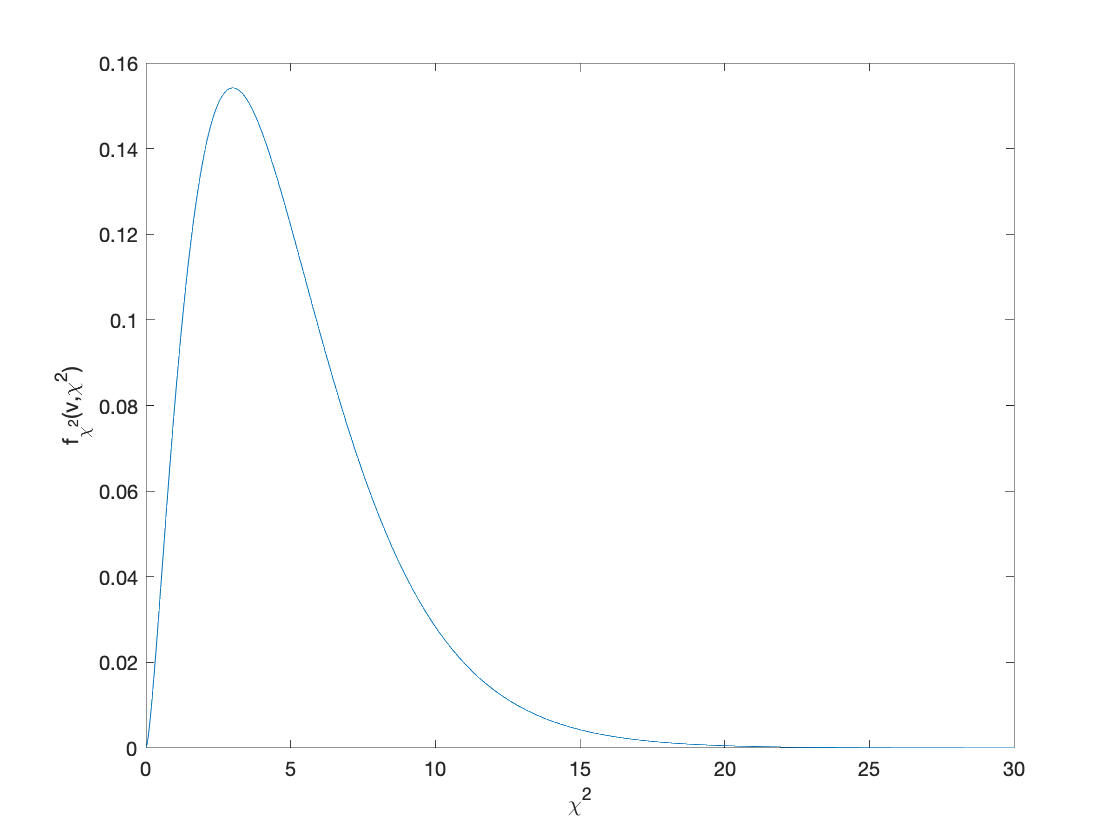

figure(2)
chi2=linspace(0,30,1000);
plot(chi2,chi2pdf(chi2,nu));
xlabel('\chi^2')
ylabel('f_{\chi^2}(v,\chi^2)')

The value of $\chi^2 = 4.8945$ falls much closer to the mode of thed istribution than either of the tails. The P − value for this statistic is

P=chi2cdf(chi2stat,nu,"upper")

P =    4.2889e-01


## Normal Correlation Analysis

Recall that in an earlier example on regression, we presented a data set that summarized the annual salary and years in service for a sample of employees. the data set consists of just two columns of numerical observations: the years of experience for various employees, and their annual salaries. The data is restated here for convenience.

data=readtable('SalaryData.csv','ReadVariableNames',false);
data.Properties.VariableNames = {'YearsExperience','Salary'}

data = 30×2 table
    YearsExperience      Salary  
    _______________    __________

      1.1000e+00       3.9343e+04
      1.3000e+00       4.6205e+04
      1.5000e+00       3.7731e+04
      2.0000e+00       4.3525e+04
      2.2000e+00       3.9891e+04
      2.9000e+00       5.6642e+04
      3.0000e+00       6.0150e+04
      3.2000e+00       5.4445e+04
      3.2000e+00       6.4445e+04
      3.7000e+00       5.7189e+04
      3.9000e+00       6.3218e+04
      4.0000e+00       5.5794e+04
      4.0000e+00       5.6957e+04
      4.1000e+00       5.7081e+04
      4.5000e+00       6.1111e+04
      4.9000e+00       6.7938e+04


Build the regression model.

mdl=fitlm(data.YearsExperience,data.Salary)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   __________    __________    __________    __________

    (Intercept)    2.5792e+04    2.2731e+03    1.1347e+01    5.5120e-12
    x1             9.4500e+03    3.7875e+02    2.4950e+01    1.1431e-20


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 5.79e+03
R-squared: 0.957,  Adjusted R-Squared: 0.955
F-statistic vs. constant model: 623, p-value = 1.14e-20

The model provides the coefficient of determination for us.

R2=mdl.Rsquared.Ordinary

R2 =    9.5696e-01


This value was reasonably close to 1, so we concluded that the model fit our data well. However, we really shouldn’t be satisfied with that conclusion alone.

We could also ask about the underlying linearity of our data through hypothesis testing. A bad situation we’d like to avoid would be to derive a model that we would expect that our data could be described by a bivariate normal distribution with ρ = 0 as a correlation coefficient parameter. If that were to be the case, then we would expect that our data is uncorrelated and cannot be described well by a linear model. Therefore, we would state the following null hypothesis:

$H_0$ : Our sample is drawn from a bivariate normal distribution with $\rho=0$.

The sample correlation coefficient and z statistic for our regression data become

n=height(data);
r=sqrt(R2);
z=(sqrt(n-3)/2)*log((1+r)/(1-r));

Finally, we ask the question, “given the assumption that $H_0$ is true, how likely is it that we would expect to collect a similarly sized sample from our population that produces a sample correlation coefficient at least as extreme as the one we’ve found? The answer would be

P=normcdf(z,"upper")

P =    5.2008e-32
